# **Detección de fallos en motores usando acelerometro y el Classification Learner Toolbox de Matlab**

Estudiantes:

- **Pablo**

- **Neisser**

Características del experimentos:

- 1-Todo funcional

- 2-Avería en el eje

- 3-Sin dos fijaciones

- 4-Sin dos fijaciones y avería en el eje

Características del hardware:

- Frecuencia de muestreo: 100Hz

- Sensor MPU6050 (acelerometro y giroscopio)

Referencias:

- **Funciones de Matlab: **[**https://github.com/vasanza/Matlab_Code**](https://github.com/vasanza/Matlab_Code)

- **Proyecto de referencia: **[**https://vasanza.blogspot.com/2021/01/phrases-recognition-with-machine.html**](https://vasanza.blogspot.com/2021/01/phrases-recognition-with-machine.html)

- **Ejemplo de clasificacón EMG: **[**https://vasanza.blogspot.com/2020/01/alphabet-letters-recognition-with.html**](https://vasanza.blogspot.com/2020/01/alphabet-letters-recognition-with.html)

- **Ejemplo de clasificacón EEG: **[**https://vasanza.blogspot.com/2020/01/eeg-signal-classification-with-machine.html**](https://vasanza.blogspot.com/2020/01/eeg-signal-classification-with-machine.html)

Notas para el uso:

- Se recomienda organizar los datos en la carpeta "data" y las funciones en la carpeta "src".

- Para ejecutar el codigo principal "main.mlx", poner el current folder en la misma ubicación.

- **En el siguiente enlace se puede revisar como fue desarrollado el presente codigo: **[**https://youtu.be/UI7Oa1sXEeY**](https://youtu.be/UI7Oa1sXEeY)

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
folderNames=FindFolders(datapath);
allData=[];
for j=1:length(folderNames)
    path1=fullfile(datapath,folderNames(j).name);
    filenames = FindCSV(path1);%List All CSV files
    for i=1:length(filenames)% Through all files
        data=readtable(fullfile(path1,filenames(i).name));%Select i CSV file
        %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
        %data=[data(:,2) data(:,5:end)];
        dataNew=table2array(data);% Array Double
        dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
        Label=str2double(filenames(i).name(2));%<-- caracter que identifica la tarea
        allData=[allData;[rms(dataNew) Label]];
    end
end

# 2- Grafica de datos

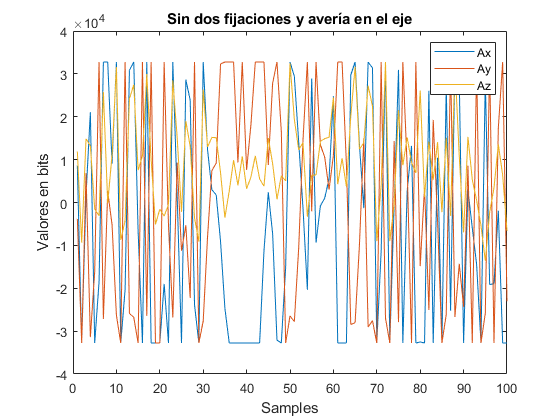

%Plot de las señales del ultimo archivo (tarea 4)
plot(dataNew);
legend('Ax','Ay','Az');
title('Sin dos fijaciones y avería en el eje');
xlabel('Samples');
ylabel('Valores en bits');

xlim([0.0 100.0])
ylim([-40000 40000])

%Features
rms(dataNew)

ans = 	1.0e+04 *

    2.5987    2.5387    1.4382


# 3- Classification

%index1 = find(allData(:,2)==1);%Incluir esta clase en la clasificación
%index2 = find(allData(:,2)==4);%Incluir esta clase en la clasificación
%BinaryData=[allData(index1,:);allData(index2,:)];
%[RandomData,IndexRows] = fRandomize_DataRows(BinaryData);
%[Training, Validation] = fsplit_data(RandomData, 0.7);

[RandomData,IndexRows] = fRandomize_DataRows(allData);
[Training, Validation] = fsplit_data(RandomData, 0.7);%70% para Training y 30% para validation
%clear data dataNew;

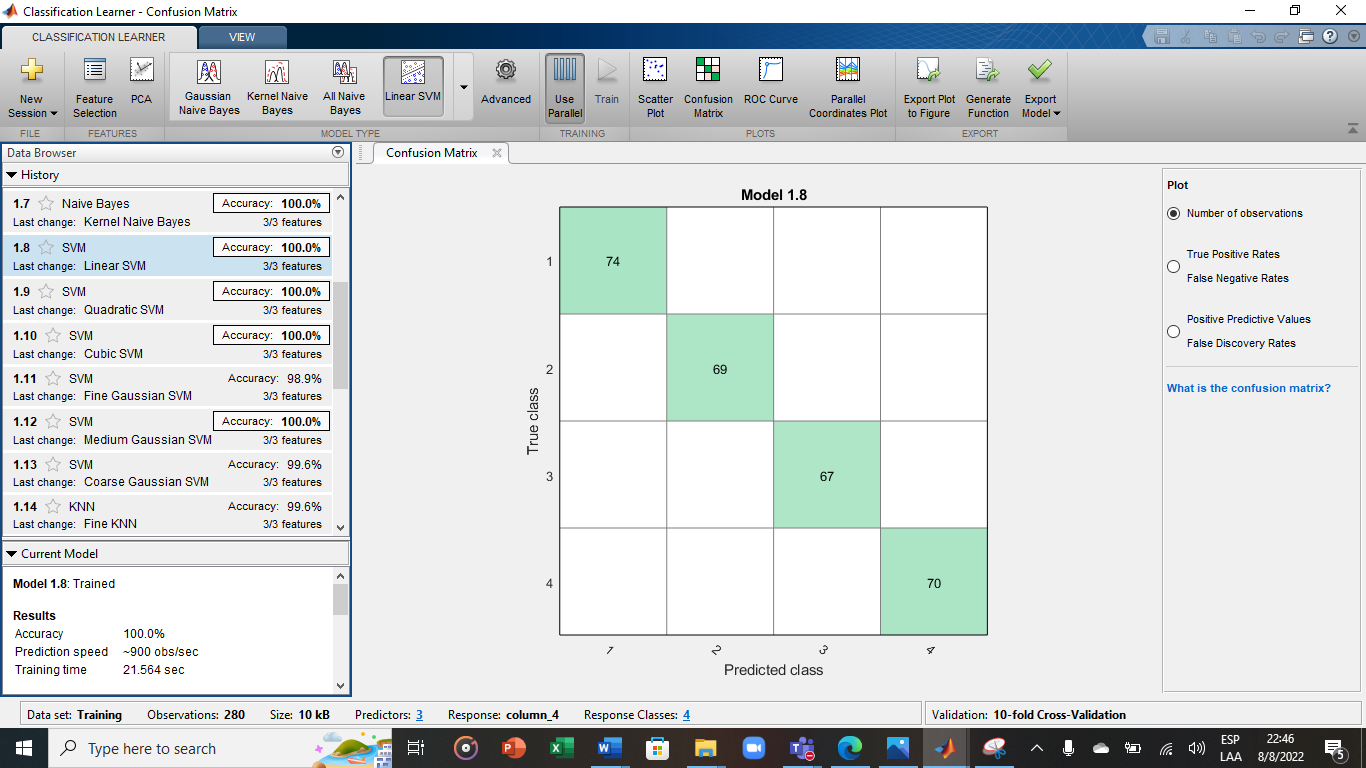

# 3- Validation

[trainedClassifier, validationAccuracy]=trainClassifierLinearSvm(Training);

yfit = trainedClassifier.predictFcn(Validation(:,1:3));
TrueClass=Validation(:,4);
%compare=[yfit TrueClass];
compare=[yfit - TrueClass];
%sum(compare);

# 4- ThingSpeak

https://github.com/vasanza/Matlab_Code/blob/main/LinearRegression_ThingSpeak.m

%tarea